close all;
clear variables;

breath = importdata("C:\Users\hp\Desktop\get-for-10\sound\data\breath.txt");
breathRaw = breath.data;

air = importdata("C:\Users\hp\Desktop\get-for-10\sound\data\air.txt");
airRaw = air.data;

tt = importdata("C:\Users\hp\Desktop\get-for-10\sound\data\TotalTime.txt");
tt = tt.data;

fr = importdata("C:\Users\hp\Desktop\get-for-10\sound\data\samplingFrequency.txt");
fr = fr.data;

T = importdata("C:\Users\hp\Desktop\get-for-10\sound\data\temperature.txt");
T = T.data;

w = importdata("C:\Users\hp\Desktop\get-for-10\sound\data\volumeFractionWater.txt");
w = w.data;

%Нормировка

windowSize = 5;
b = (1/windowSize) * ones(1, windowSize);
a = 1;

airFiltered = filter(b, a, airRaw());
breathFiltered = filter(b, a, breathRaw());

start = 30;

airFiltered = airFiltered(start:end, :);
breathFiltered = breathFiltered(start:end, :);
fr = 1/fr;
time = (0:fr:tt)';
time = time(start:end);

cAir = polyfit(time, airFiltered(:, 1), 3);
cBreath = polyfit(time, breathFiltered(:, 1), 3);

air = airFiltered - polyval(cAir, time);
airNorm = air ./ max(air);

breath = breathFiltered - polyval(cBreath, time);
breathNorm = breath ./ max(breath);

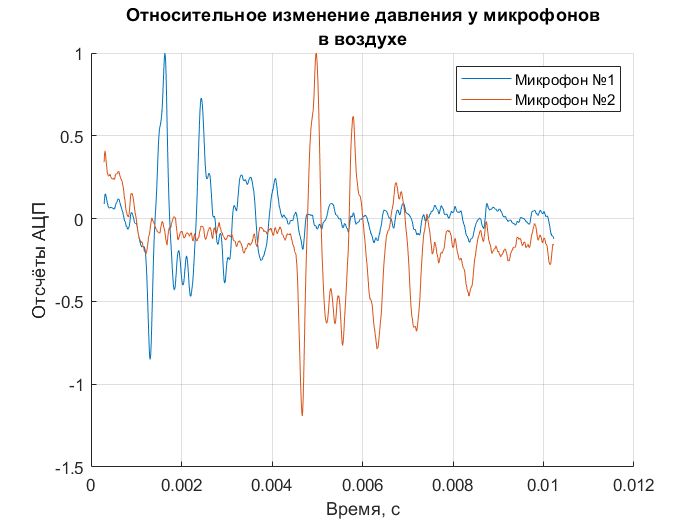

% air

zNames = {'Микрофон №1'; 'Микрофон №2'};

airF = figure();
hold on;

for i = 1:2
    plot(time, airNorm(:, i), 'DisplayName', zNames{i});
end

grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе'});
xlabel('Время, с');
ylabel('Отсчёты АЦП');

legend('Location', 'NorthEast');
saveas(airF, "C:\Users\hp\Desktop\get-for-10\sound\graph_air.png");

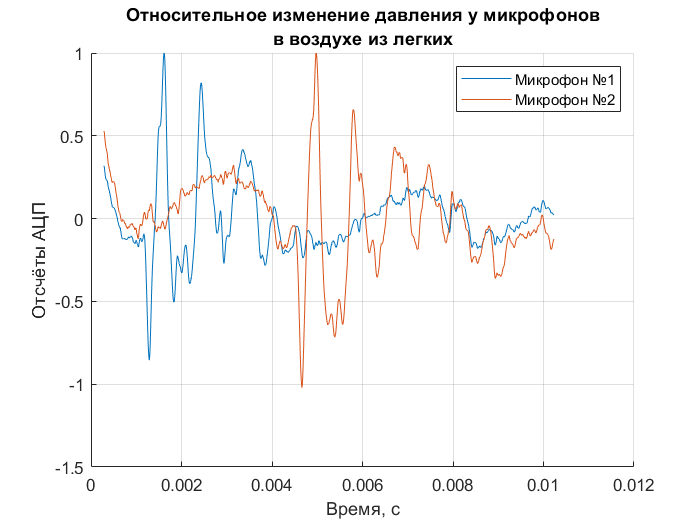

% breath

zNames = {'Микрофон №1'; 'Микрофон №2'};

breathF = figure();
hold on;

for i = 1:2
    plot(time, breathNorm(:, i), 'DisplayName', zNames{i});
end

grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе из легких'});
xlabel('Время, с');
ylabel('Отсчёты АЦП');

legend('Location', 'NorthEast');
saveas(breathF, "C:\Users\hp\Desktop\get-for-10\sound\graph_breath.png");